% Q3.3
samplerate = 16000;
t = (-5:1/samplerate:5)';
T = 0.4;
w0 = 2*pi/T;
N = 100;

ak = @(k) (((-1).^k - 1) .* (3 * ((-1).^k - 1) + 12 * (1j).^k)) ./ (2 * pi^2 * k.^2);

a0 = 2.125

a0 = 2.1250

coeffs = [ak(-N:-1) a0 ak(1:N)];
xN = exp(1i*w0*t*(-N:N)) * coeffs.';


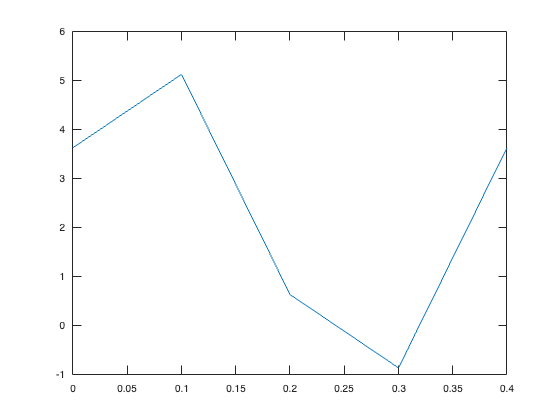

plot(t, real(xN)); xlim([0 0.4]);

% A partir de aqui foram só experiências random
syms t n L

tt = (t>0)*(2*L) + mod(t, 2*L);

aperiodic_x = piecewise(t >= 0 & t <= 0.2, (3/0.2)*t + 1, t > 0.2 & t <= 0.3, (-3/0.1)*t + 10, t > 0.3 & t <= 0.4, 1, t<0, 0, t>0.4, 0);

x = piecewise(tt >= 0 & tt <= 0.2, (3/0.2)*tt + 1, tt > 0.2 & tt <= 0.3, (-3/0.1)*tt + 10, tt > 0.3 & tt <= 0.4, 1, tt<0, 0, tt>0.4, 0);









T = 2*L;

% Compute the Fourier coefficients symbolically
a0 = (1/T) * int(x, t, -L, L); % DC term
cn = (1/T) * int(x * exp(-1i * n * pi * t / L), t, -L, L);

disp(a0)

$$\begin{array}{l} \left\{ \begin{array}{cl} \frac{\int_{-L}^{L}\left\{ \begin{array}{cl} \sigma_{7}+1<\sigma_{5} & \text{ if }t\leq L\wedge 0<L\,t\wedge 0\leq L+t\wedge \sigma_{1}\leq 1\wedge 0\leq t\mathrm{mod}2\,L\\ \sigma_{4}<10-\sigma_{6} & \text{ if }t\leq L\wedge 0<L\,t\wedge 0\leq L+t\wedge 1<\sigma_{1}\wedge \sigma_{2}\leq 3\wedge \frac{1}{5}<t\mathrm{mod}2\,L\\ 1 & \text{ if }t\leq L\wedge 0<L\,t\wedge 0\leq L+t\wedge 3<\sigma_{2}\wedge \sigma_{1}\in \left(1,2\right]\wedge \frac{3}{10}<t\mathrm{mod}2\,L\\ 0 & \mathrm{otherwise} \end{array}\right.\mathrm{d}t}{2\,L} & \text{ if }0\leq L\\ -\frac{\int_{L}^{-L}\left\{ \begin{array}{cl} \sigma_{5}<\sigma_{7}+1 & \text{ if }L\leq t\wedge 0\leq \sigma_{3}\wedge L\,t<0\wedge L+t\leq 0\wedge t\mathrm{mod}2\,L\leq \frac{1}{5}\\ 10-\sigma_{6}<\sigma_{4} & \text{ if }L\leq t\wedge L\,t<0\wedge L+t\leq 0\wedge \left(\sigma_{3}<0\vee \frac{1}{5}<t\mathrm{mod}2\,L\right)\wedge 1<\sigma_{1}\wedge t\mathrm{mod}2\,L\leq \frac{3}{10}\\ 1 & \text{ if }\left(\sigma_{1}\leq 1\vee \frac{3}{10}<t\mathrm{mod}2\,L\right)\wedge L\leq t\wedge L\,t<0\wedge L+t\leq 0\wedge \left(\sigma_{3}<0\vee \frac{1}{5}<t\mathrm{mod}2\,L\right)\wedge 3<\sigma_{2}\wedge t\mathrm{mod}2\,L\leq \frac{2}{5}\\ 0 & \mathrm{otherwise} \end{array}\right.\mathrm{d}t}{2\,L} & \text{ if }L\leq 0 \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=10\,L\,t+5\,\left(t\mathrm{mod}2\,L\right)\\ \sigma_{2}=20\,L\,t+10\,\left(t\mathrm{mod}2\,L\right)\\ \sigma_{3}=2\,L\,t+\left(t\mathrm{mod}2\,L\right)\\ \sigma_{4}=10-\sigma_{6}-60\,L\,t\\ \sigma_{5}=30\,L\,t+\sigma_{7}+1\\ \sigma_{6}=30\,\left(t\mathrm{mod}2\,L\right)\\ \sigma_{7}=15\,\left(t\mathrm{mod}2\,L\right) \end{array}$$

% Display the result
disp('Complex Fourier Coefficients (c_n):');

Complex Fourier Coefficients (c_n):


disp(cn);

var2 = subs(cn,[L,n],[0.2,1])
fplot(var2)